clear
load vibstand.mat
fs=avtb_2019_Machine_1_02_Motor_bearing_metadata.SamplingRate

fs = 25000

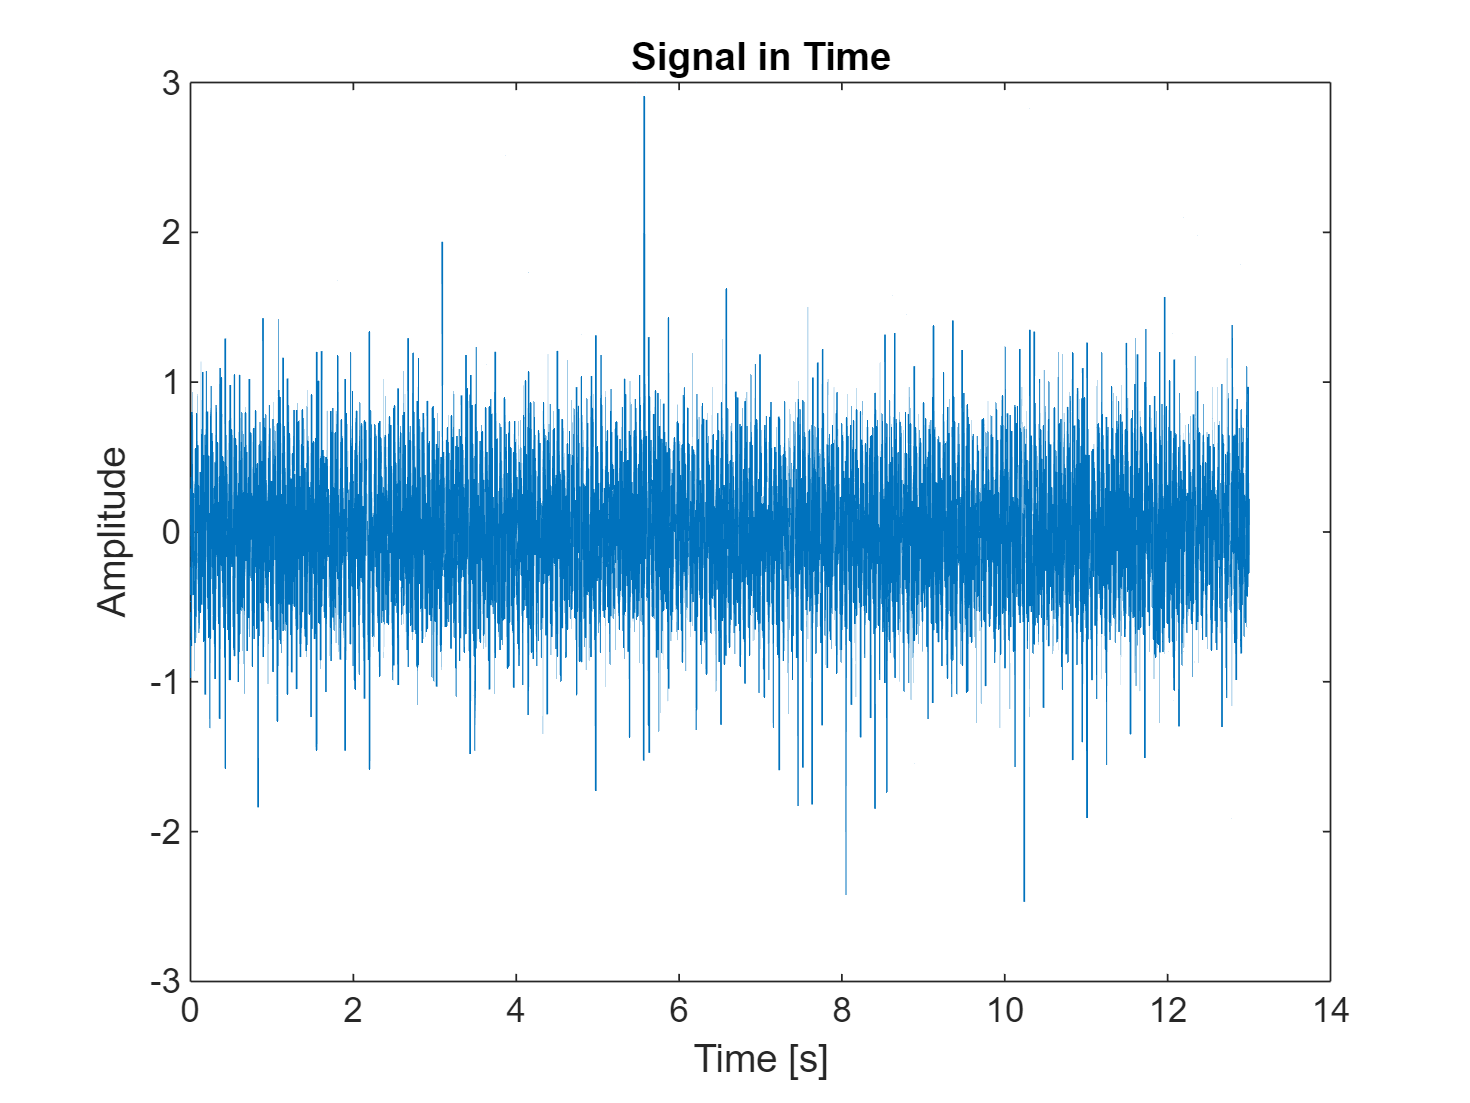


x=avtb_2019_Machine_1_02_Motor_bearing(:,2);
% N=length(x)
% t=(0:N-1)/fs;
% 
% plot(t,x)
% N=N/8
% % downsample
% fs=fs/8
% spectrogram
% x=x(1:8:end);
% length(x)
% 
% t=(0:N-1)/fs;
% length(t)
% plot(t,x)
downsampleRate=8;
[x,t,metadata]=plotSignal(x,fs,downsampleRate);                

Y=fft(x);
mag=abs(Y);
phase=angle(Y);
N=metadata.N

N = 40625

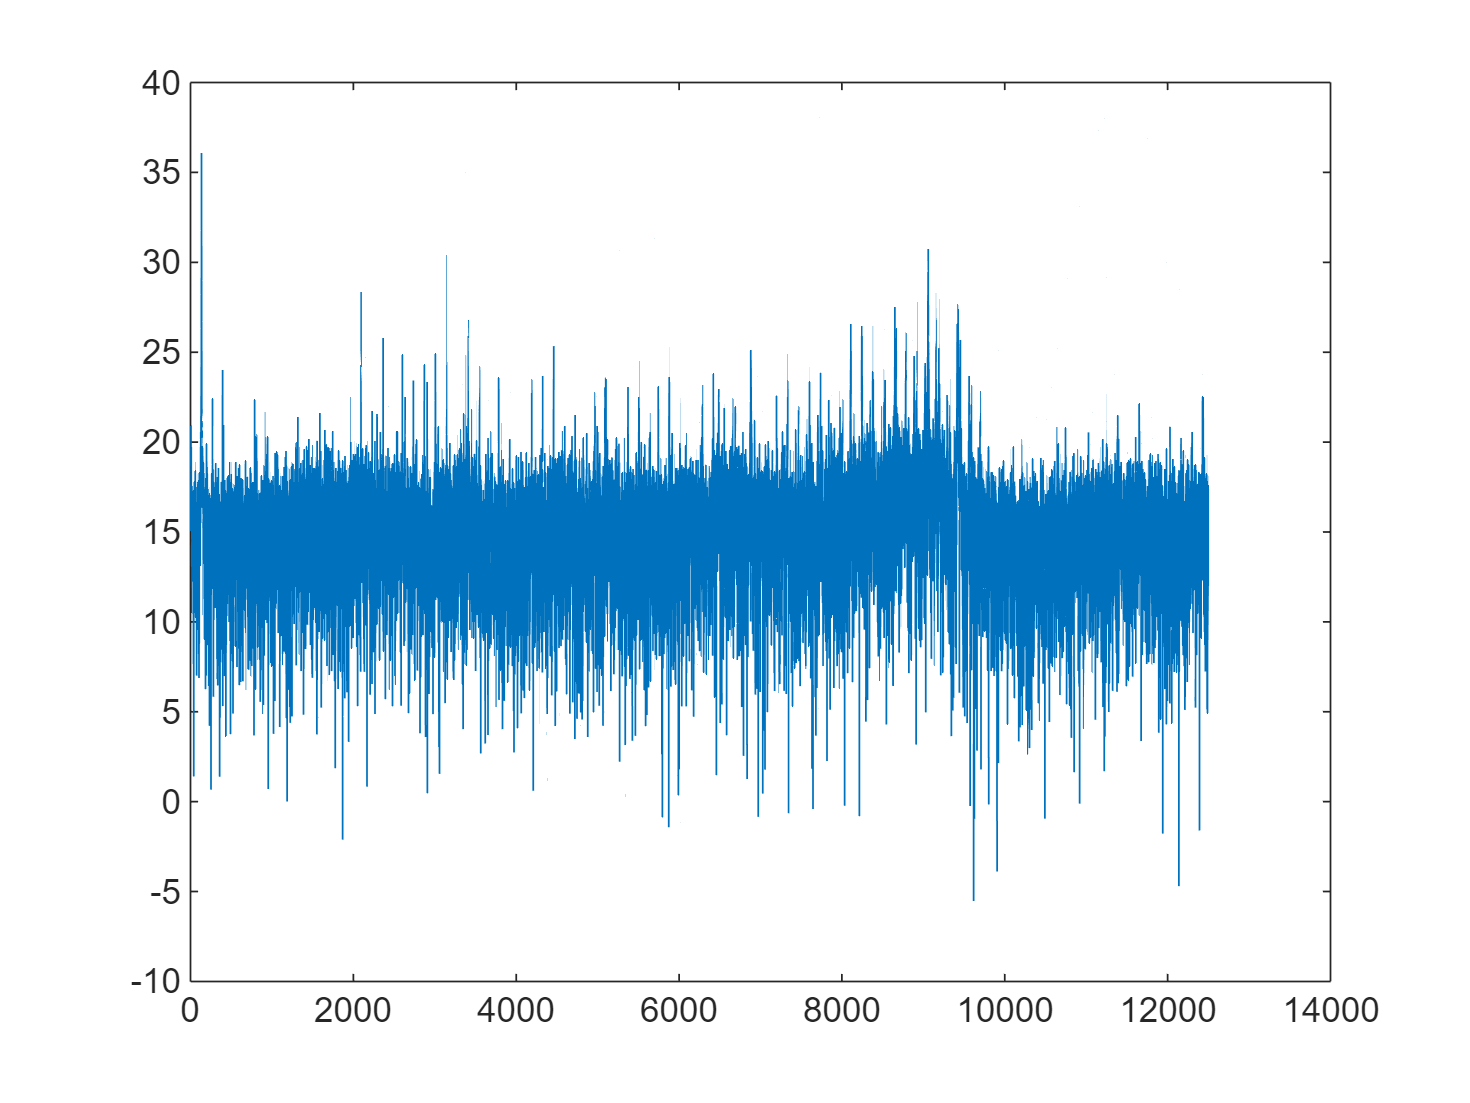

df=fs/N;
f=0:df:fs-df;
f=f';
figure
plot(f(1:floor(end/2)),10*log10(mag(1:floor(end/2))))

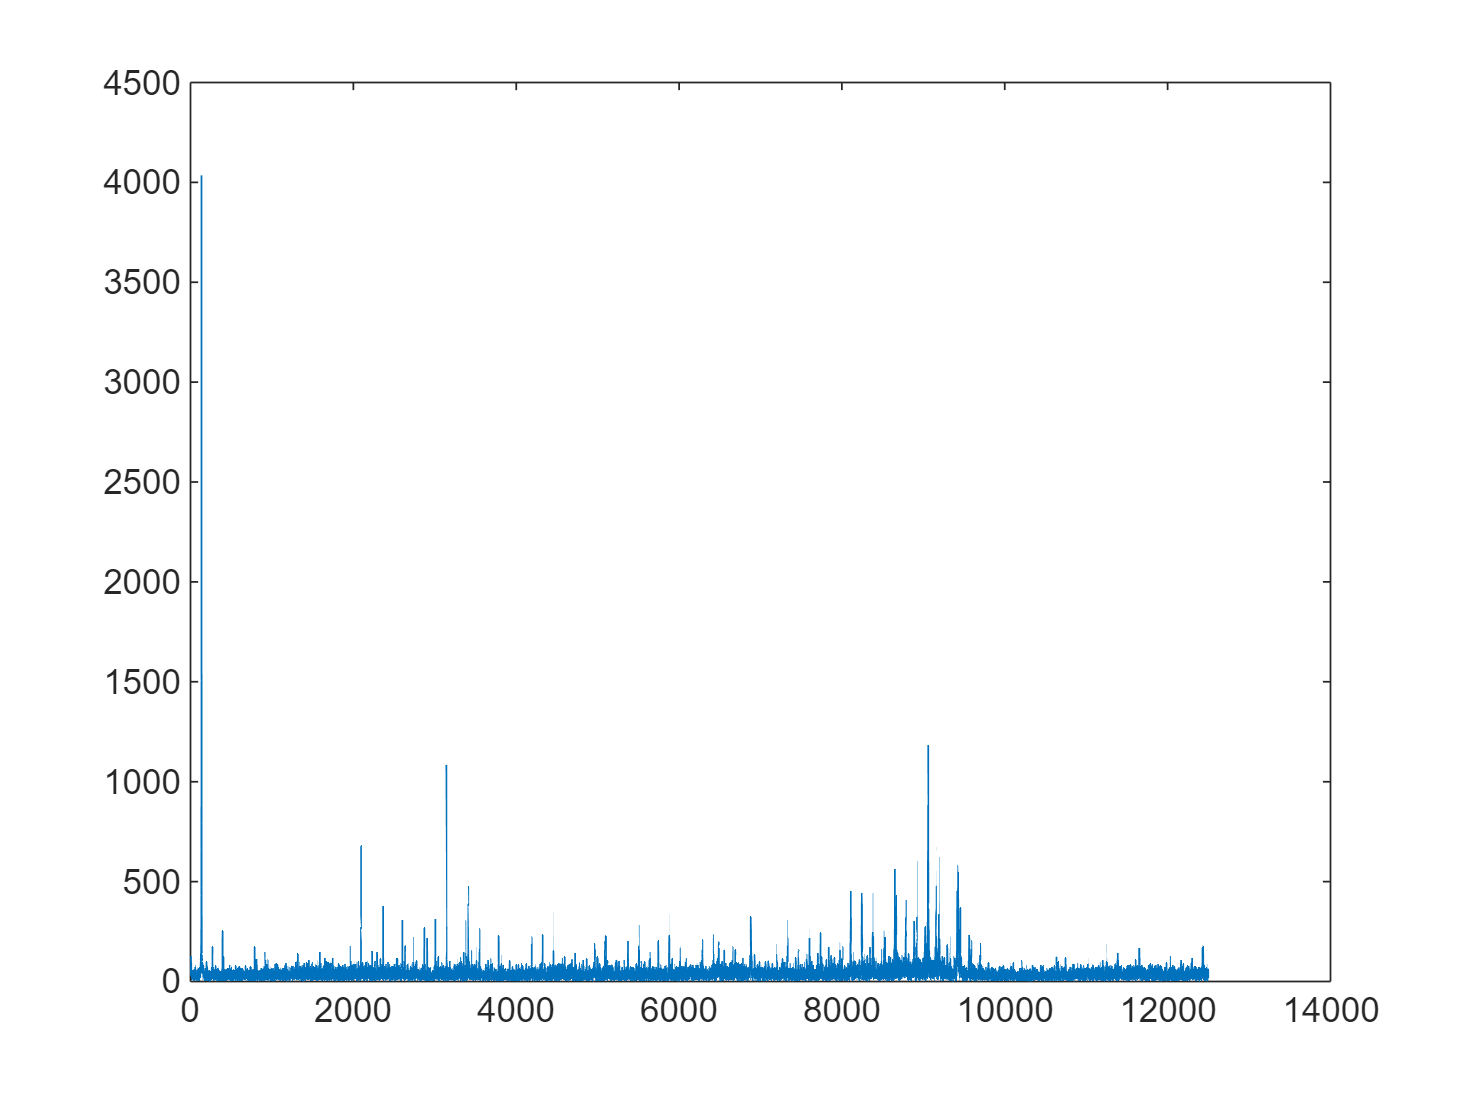

ans = 1.0e+04 *

         0    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0004    0.0005    0.0006    0.0006    0.0007    0.0007    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0012    0.0012    0.0013    0.0014    0.0014    0.0015    0.0015    0.0016    0.0017    0.0017    0.0018    0.0018    0.0019    0.0020    0.0020    0.0021    0.0022    0.0022    0.0023    0.0023    0.0024    0.0025    0.0025    0.0026    0.0026    0.0027    0.0028    0.0028    0.0029    0.0030    0.0030


figure
freqPlot(x,fs)

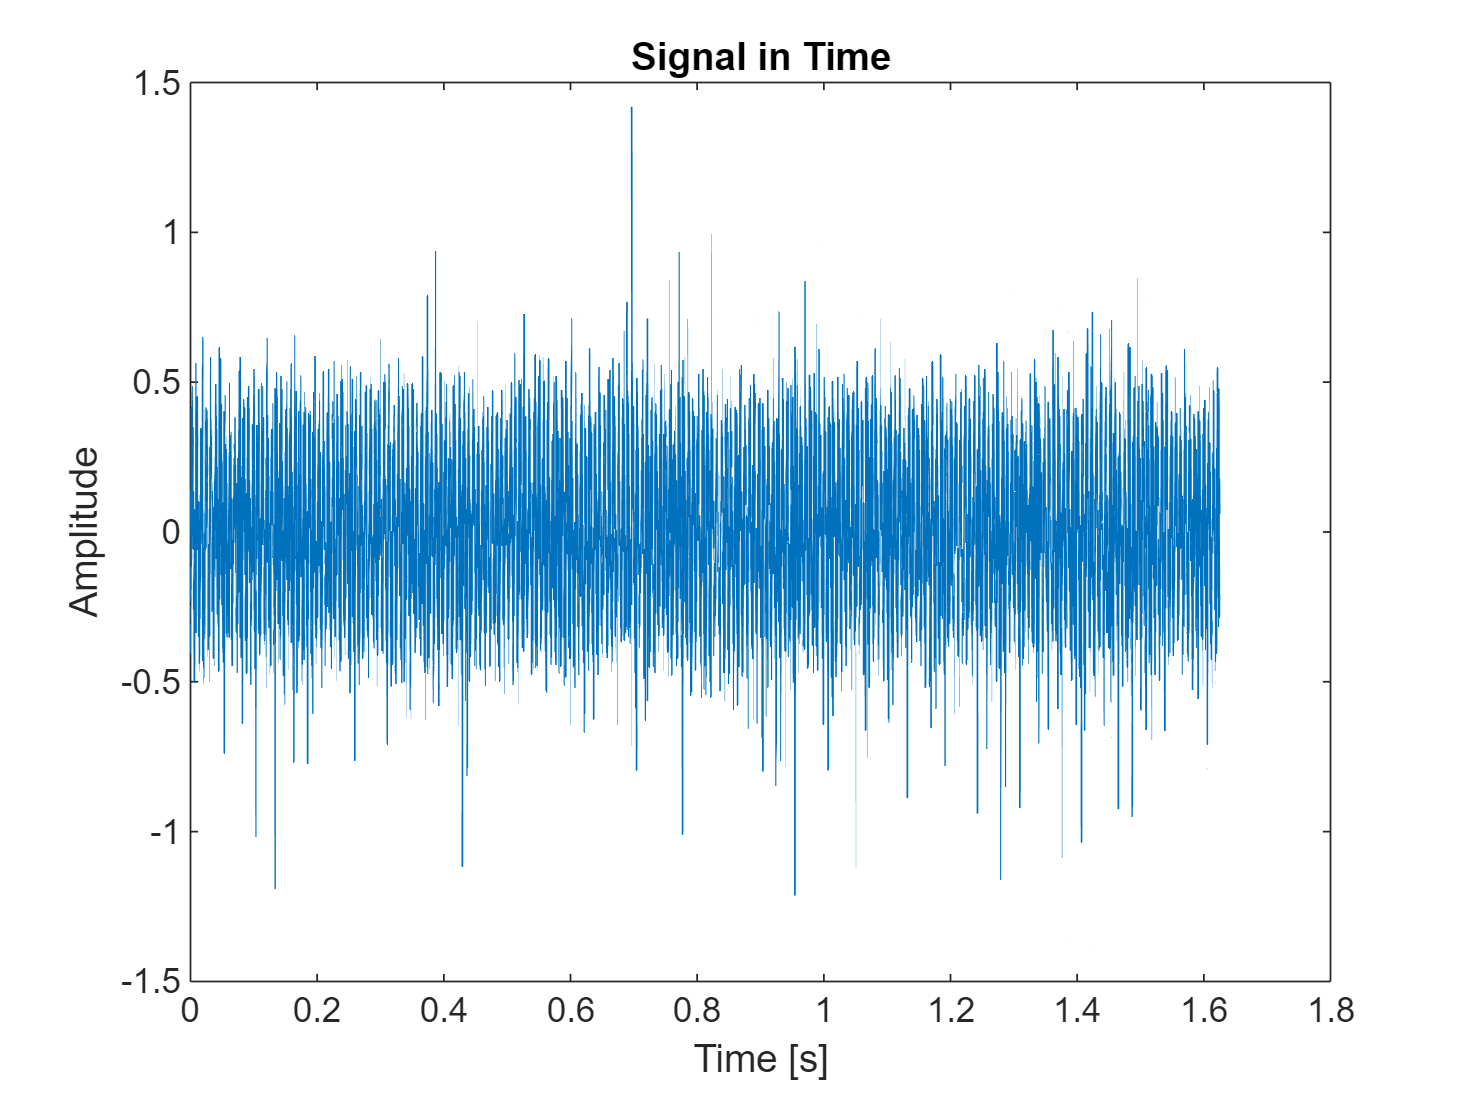

filtered=lowpass(x,5000,fs);
plotSignal(filtered,fs);

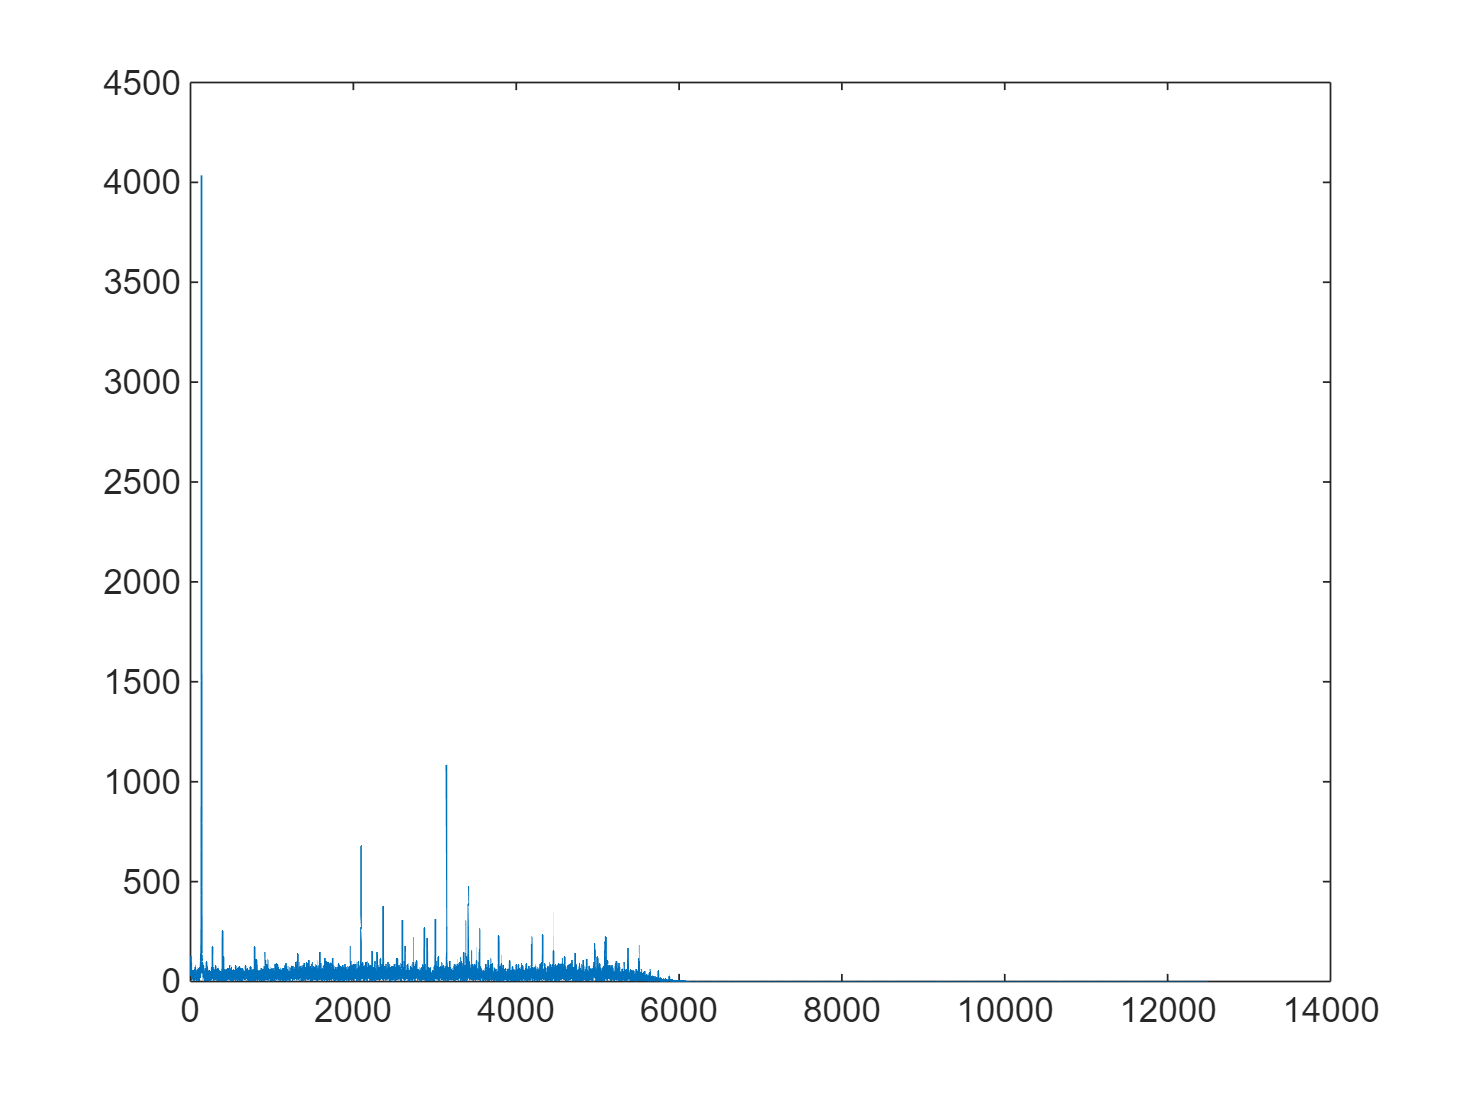

freqPlot(filtered,fs);

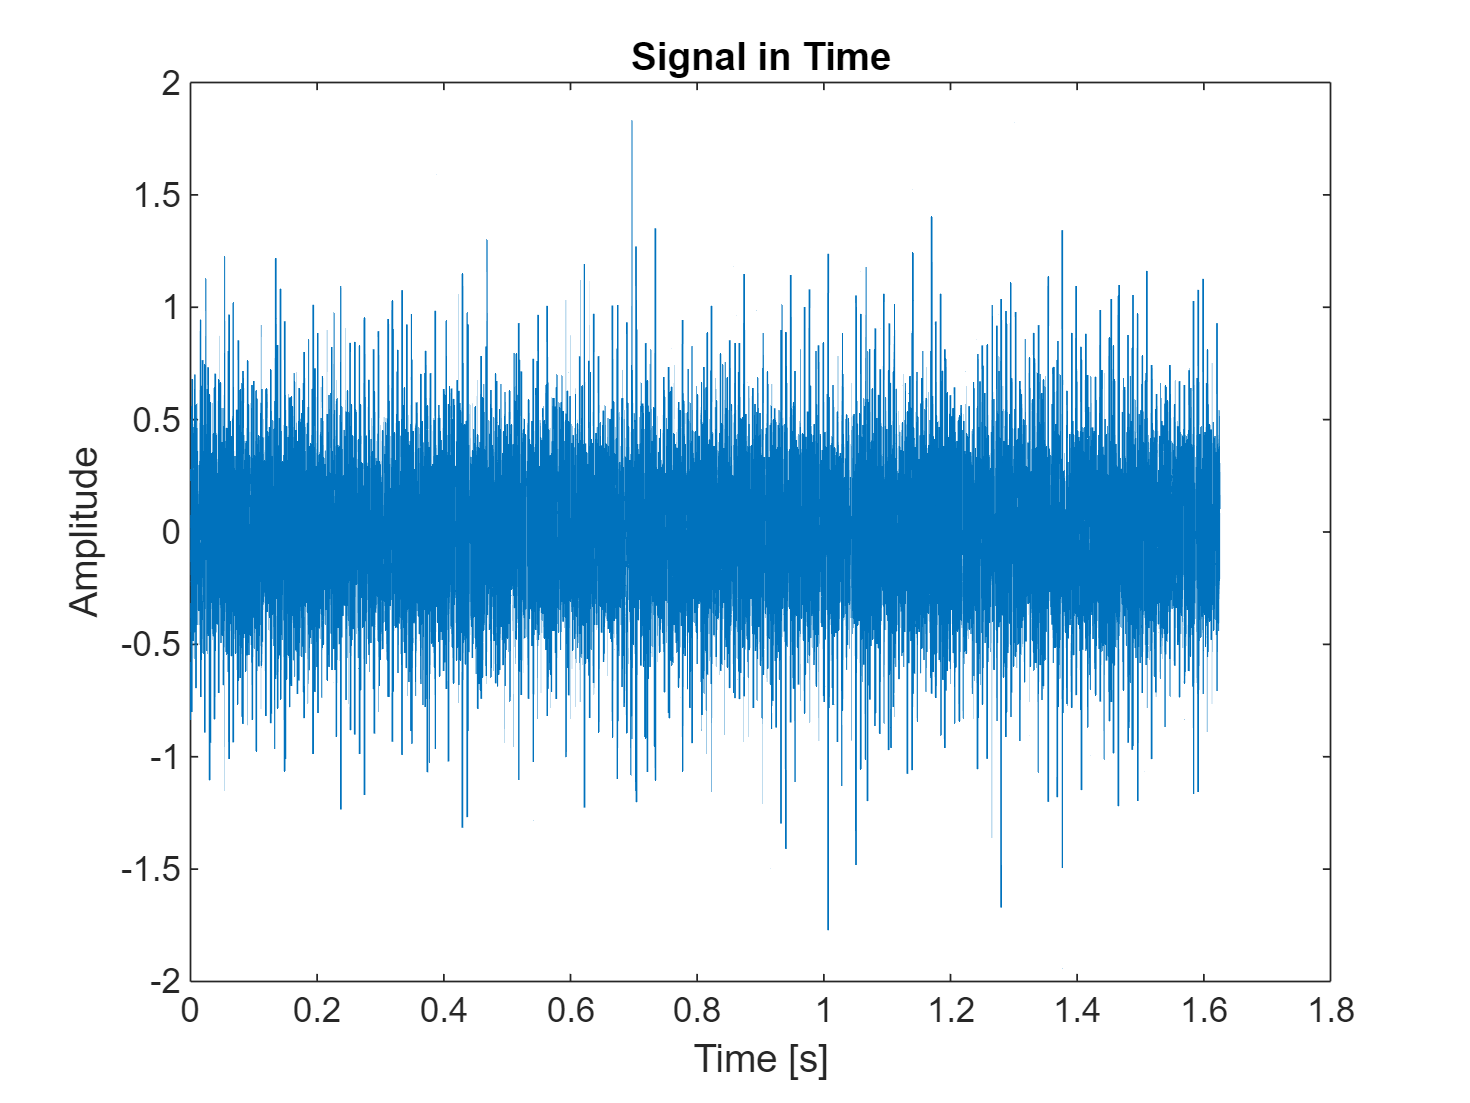

filtered2=bandpass(x,[2000,10000],fs);
plotSignal(filtered2,fs);

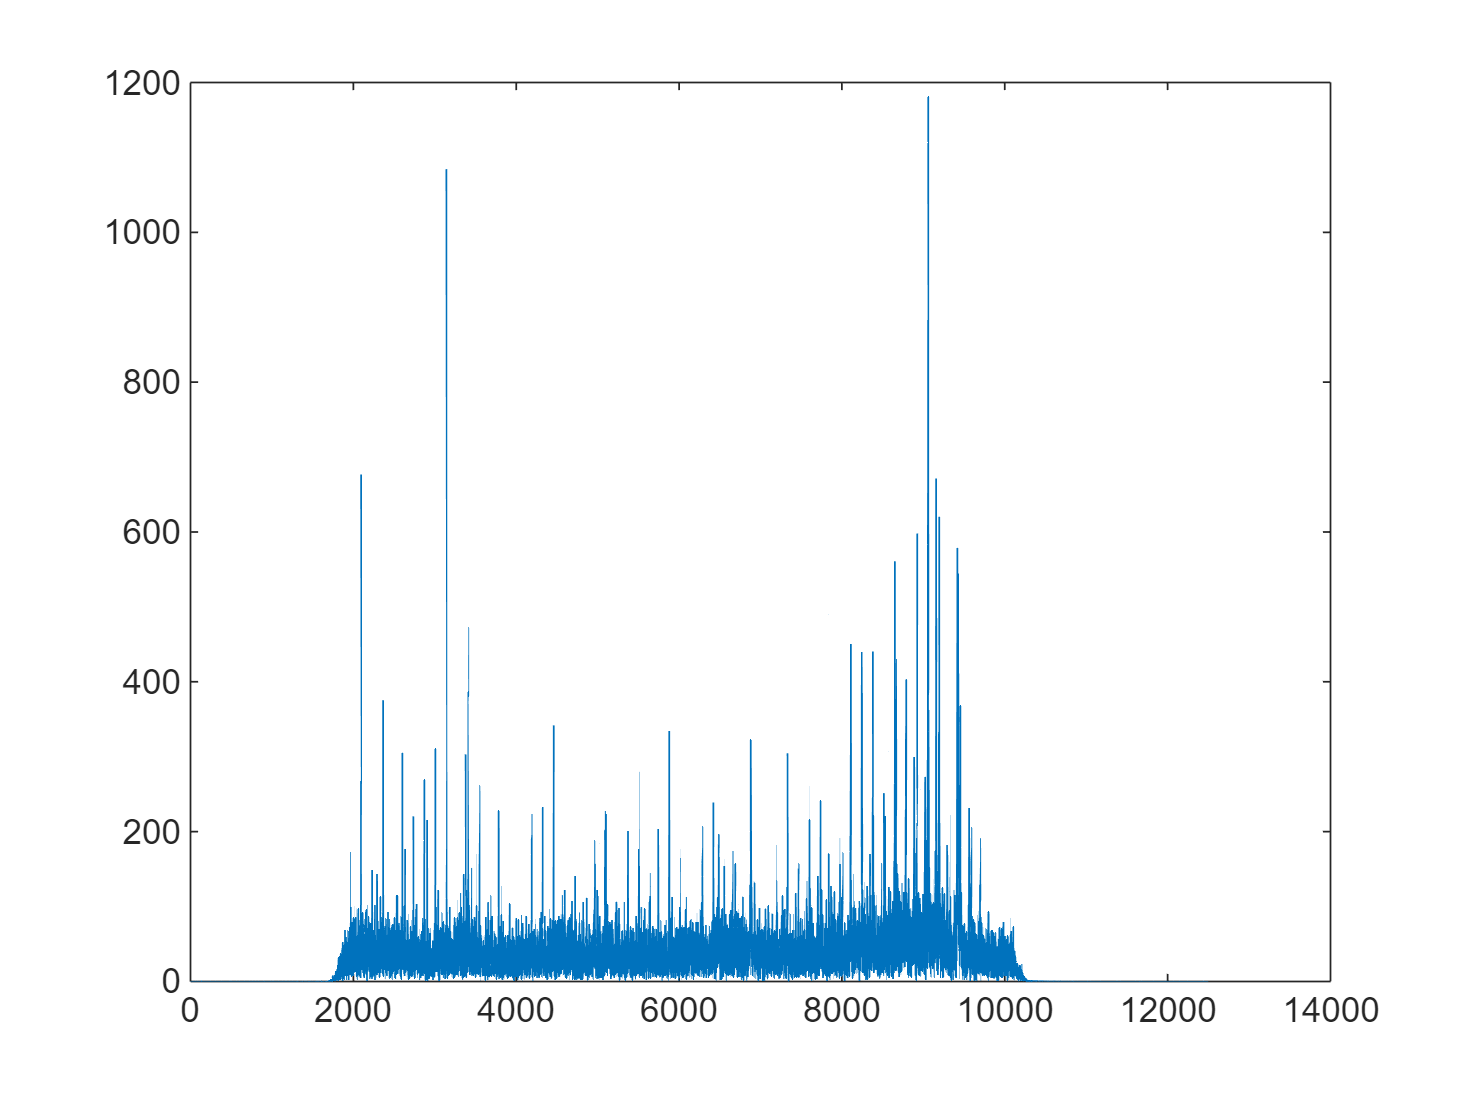

freqPlot(filtered2,fs);

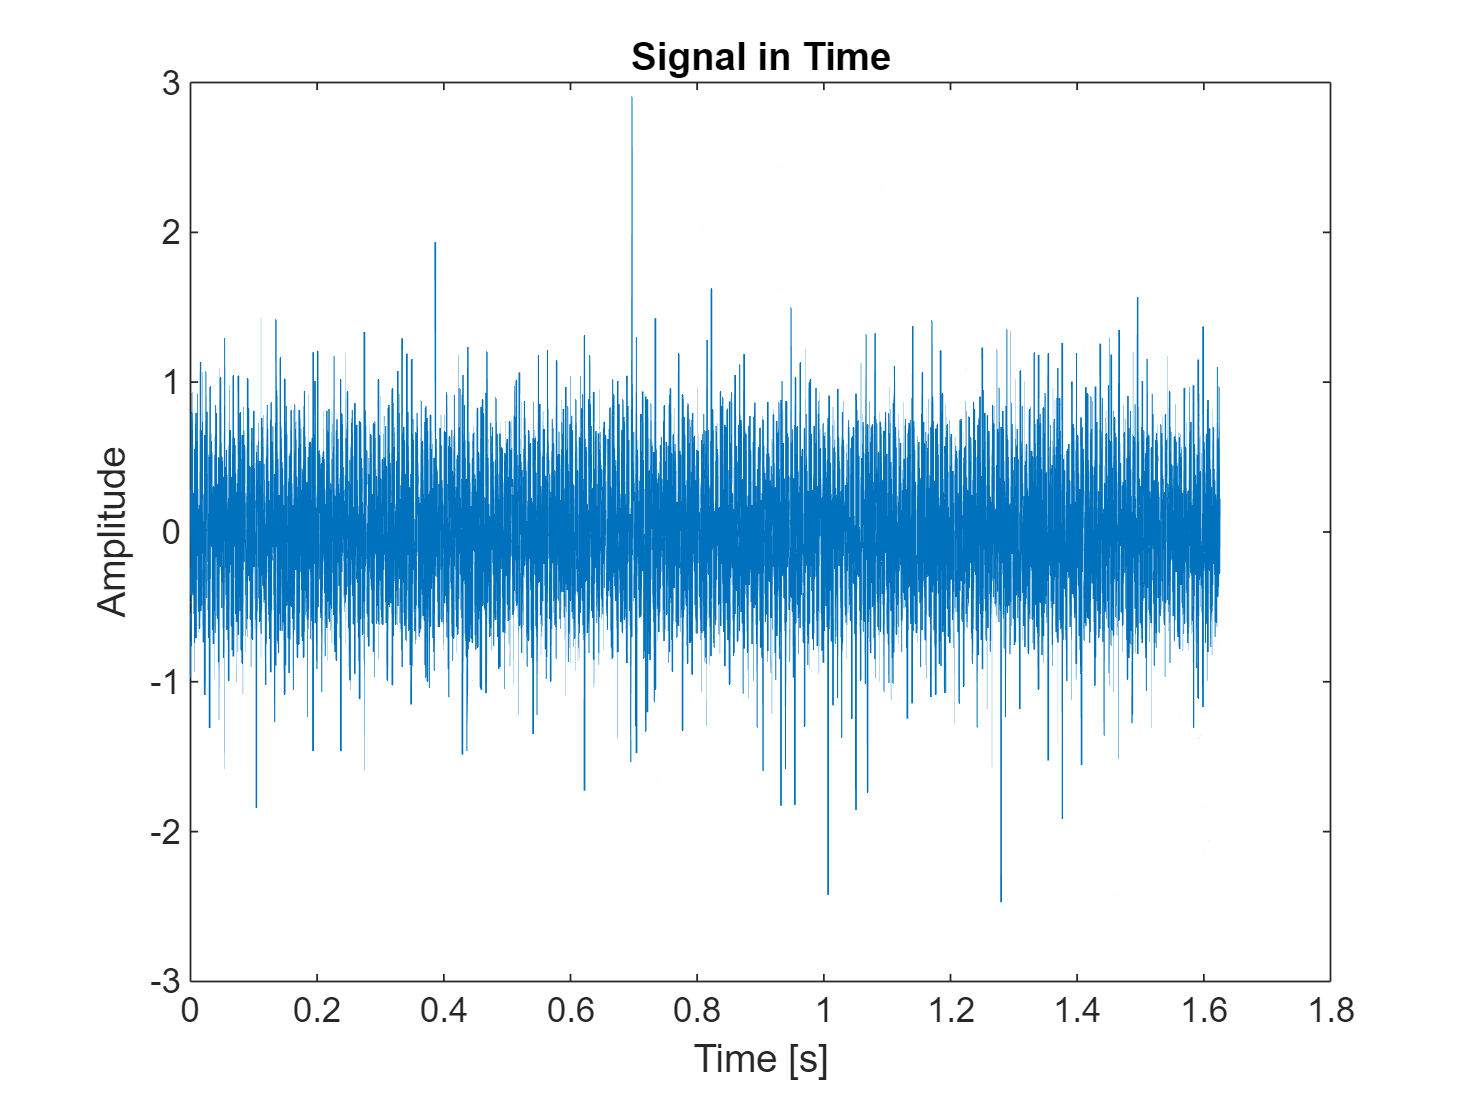

ans =     0.2871
   -0.0047
   -0.2855
   -0.3131
   -0.0585
   -0.0305
   -0.1293
   -0.4145
   -0.2260
    0.0721


detrended=detrend(x);

plotSignal(detrended,fs)

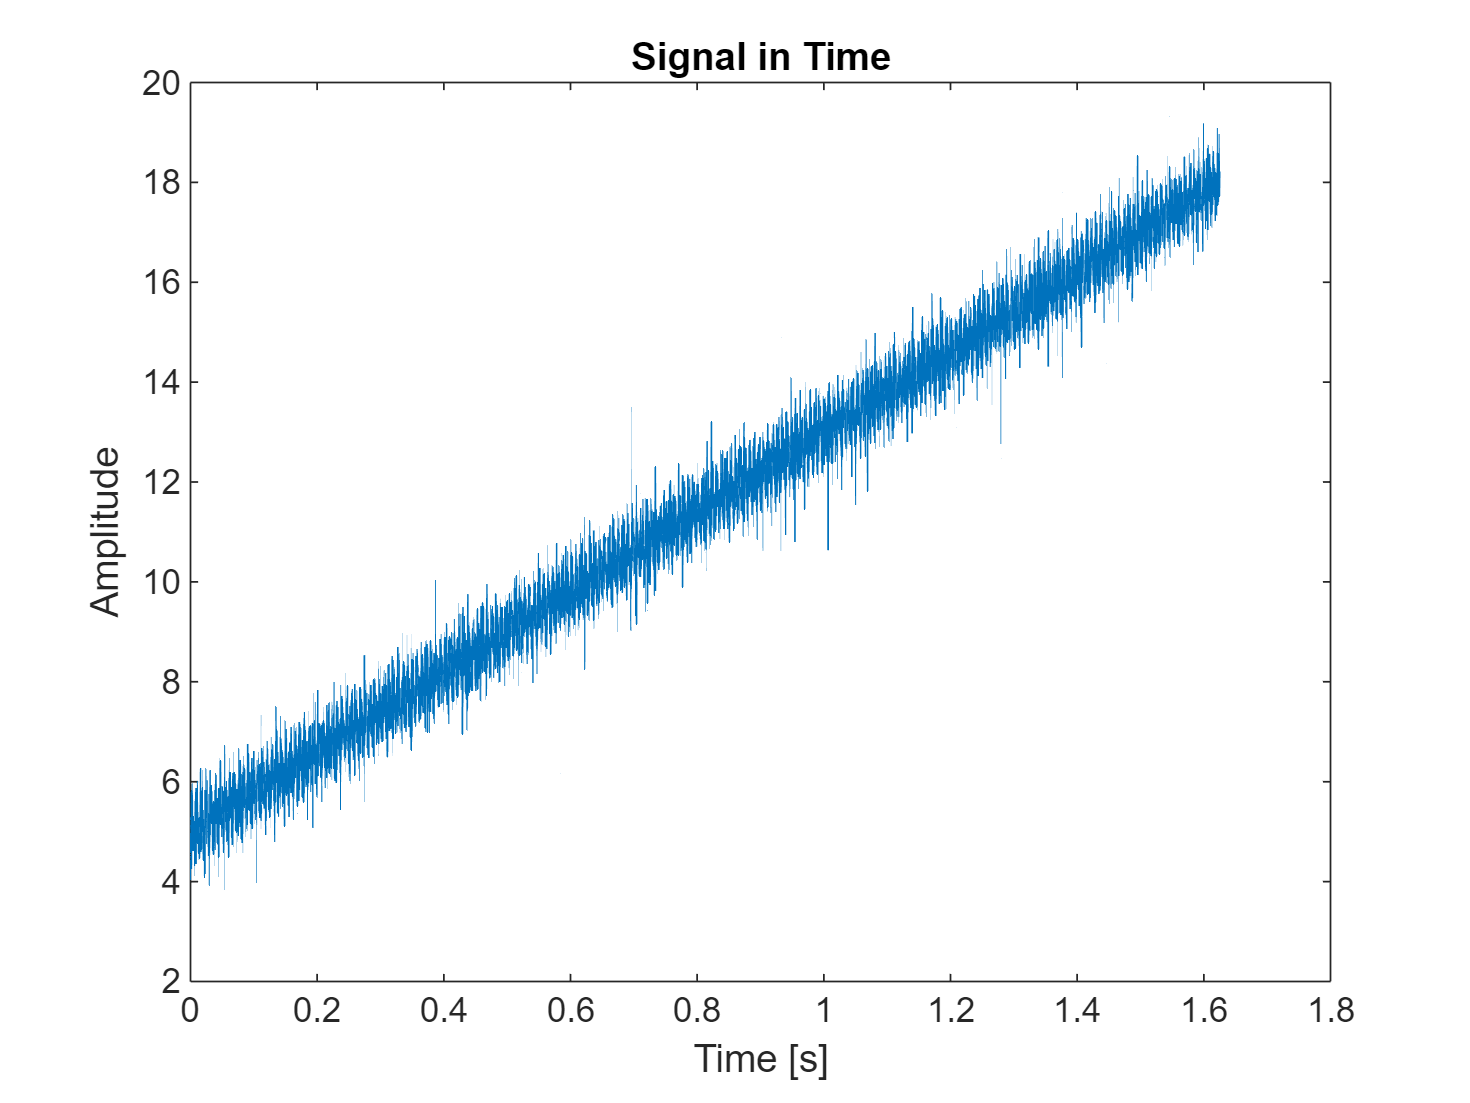

trend=t+5;
plotSignal(x+trend,fs);

detrended=detrend(x+trend);

plotSignal(detrended,fs);

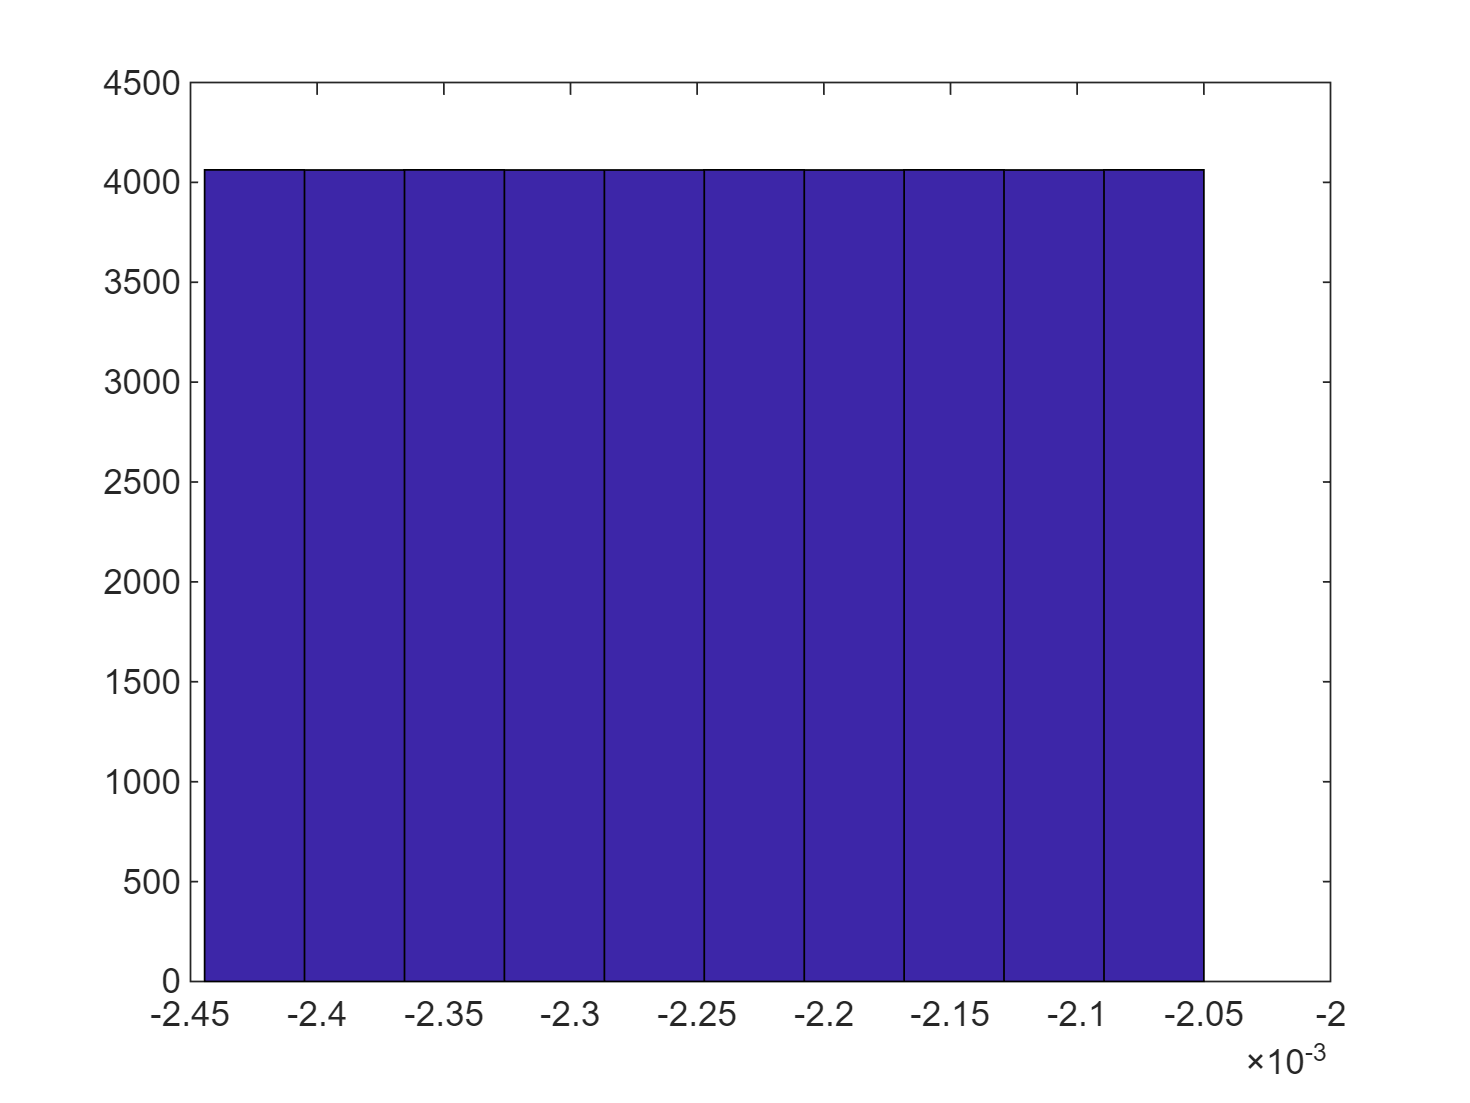


hist(detrended-x)

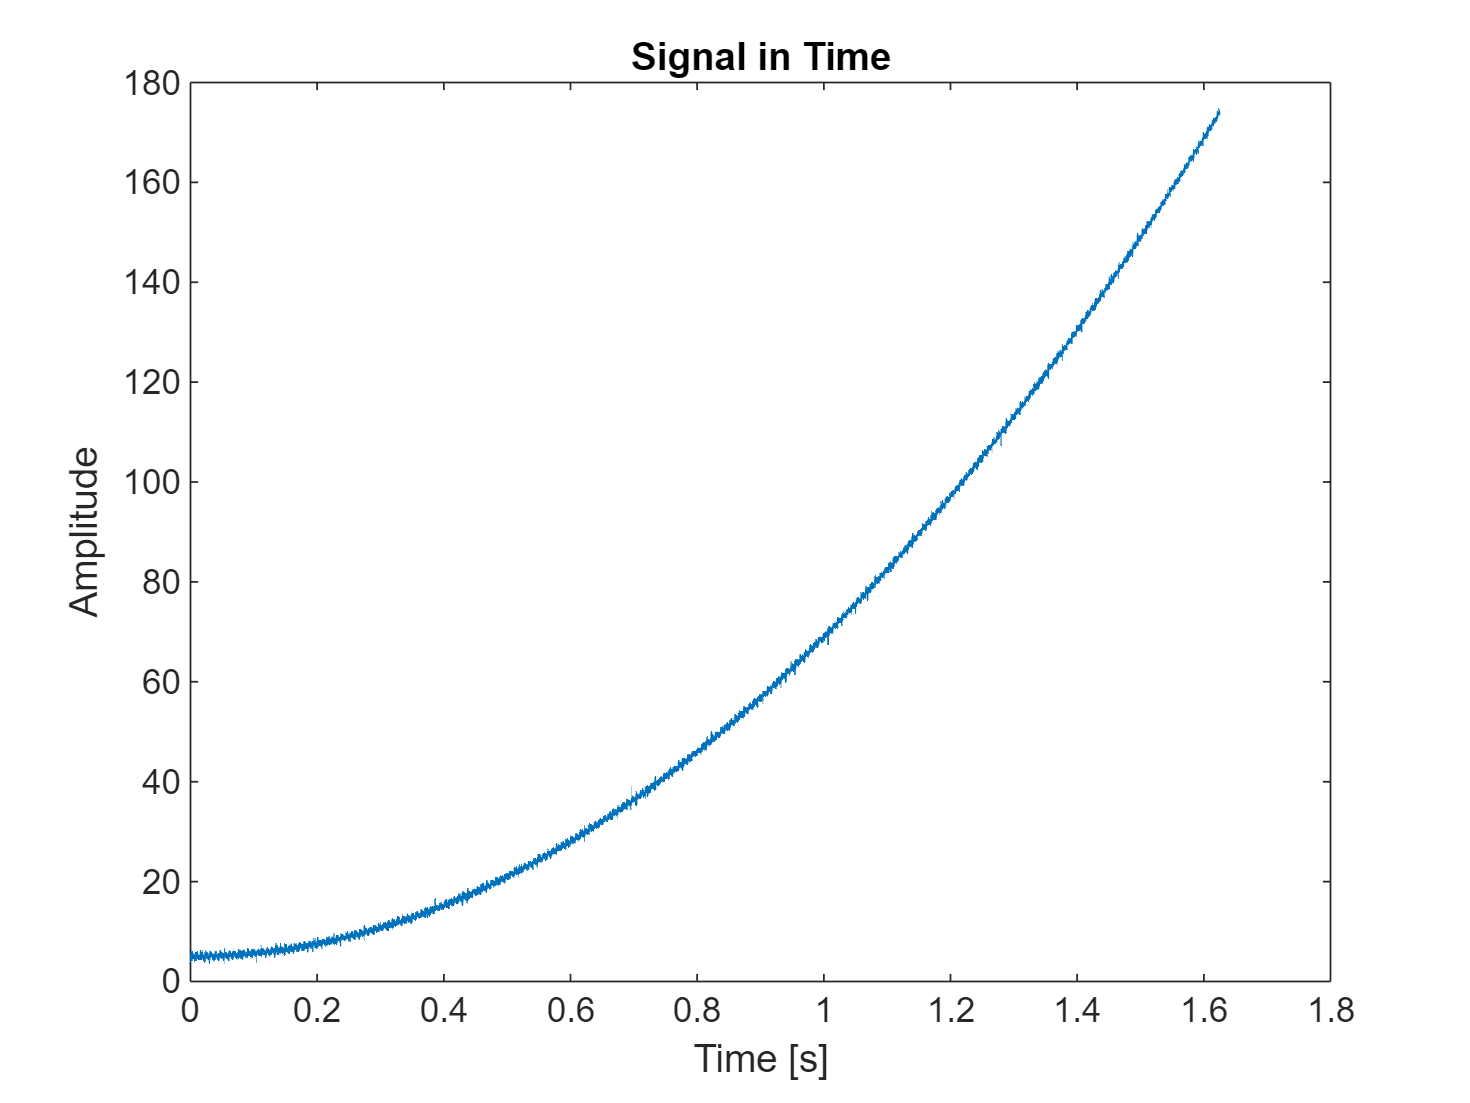


trend2=t.^2+5;
plotSignal(x+trend2,fs);

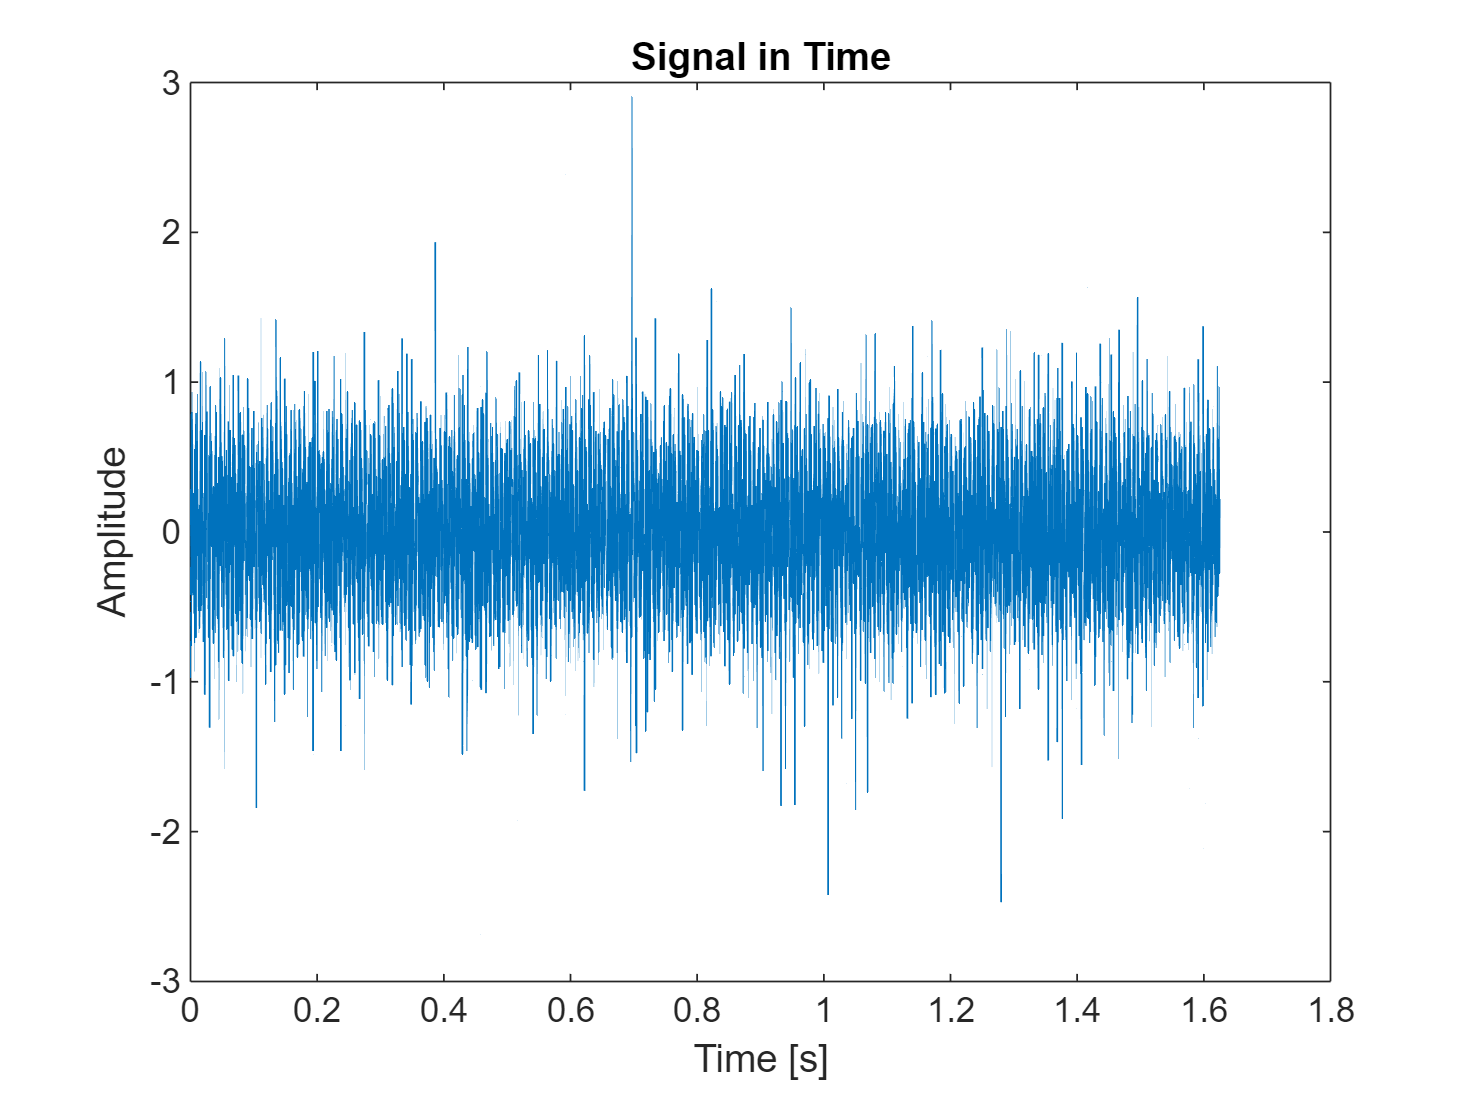

detrended2=detrend(x+trend2,2);
plotSignal(detrended2,fs);

**Time-Domain Differentiation**

% Differentiate in the time domain
dy_dt = gradient(x, 1/fs); % First derivative (numerical differentiation)
% Plot results
figure;
subplot(2,1,1);
plot(t, x, 'b', 'DisplayName', 'Original Signal');
hold on;
plot(t, dy_dt, 'r--', 'DisplayName', 'Time-Domain Derivative');
legend;
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain Differentiation');
grid on;
hold off;

**Frequency-Domain Differentiation**

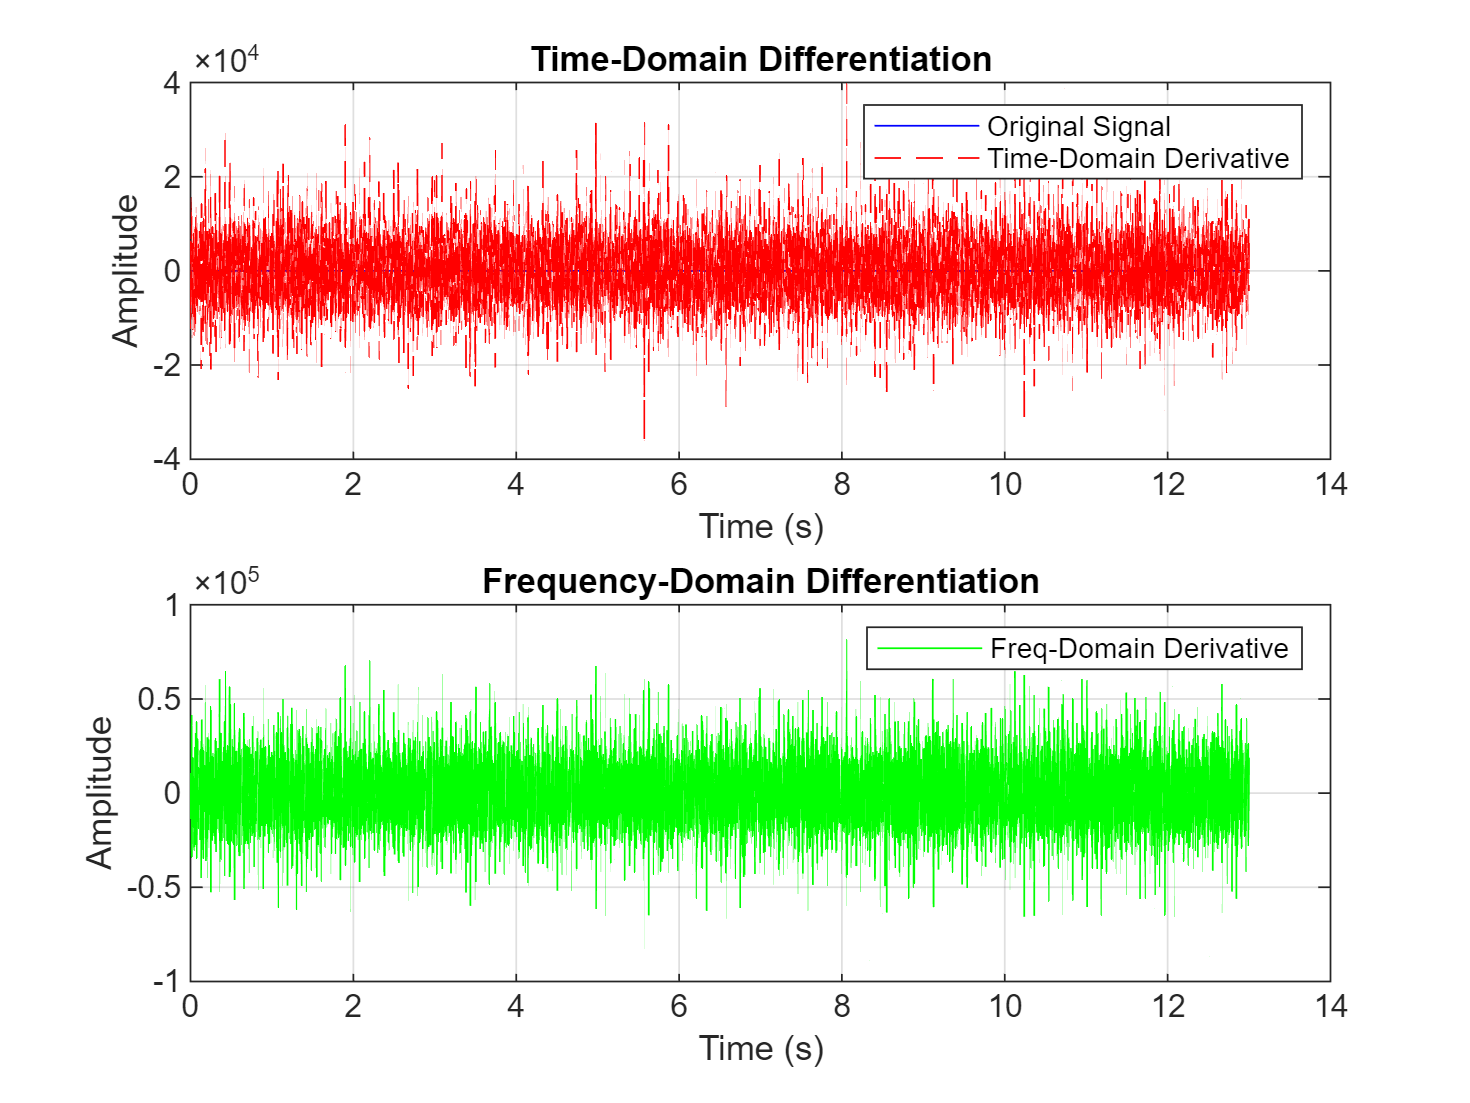

omega = 2 * pi * f;
% Apply differentiation in the frequency domain
Y_diff_f = 1j * omega .* Y; % Multiply by jω
% Compute inverse FFT to return to time domain
y_diff_f = ifft(Y_diff_f, 'symmetric');
% Plot results
subplot(2,1,2);
plot(t, y_diff_f, 'g', 'DisplayName', 'Freq-Domain Derivative');
legend;
xlabel('Time (s)');
ylabel('Amplitude');
title('Frequency-Domain Differentiation');
grid on;

Time-Domain Integration

% Integrate in the time domain
y_integrated = cumtrapz(t, x); % Cumulative integral

% Plot results
figure;
subplot(2,1,1);
plot(t, x, 'b', 'DisplayName', 'Original Signal');
hold on;
plot(t, y_integrated, 'r--', 'DisplayName', 'Time-Domain Integral');
legend;
xlabel('Time (s)');
ylabel('Amplitude');
title('Time-Domain Integration');
grid on;
hold off;

**Frequency-Domain Integration**

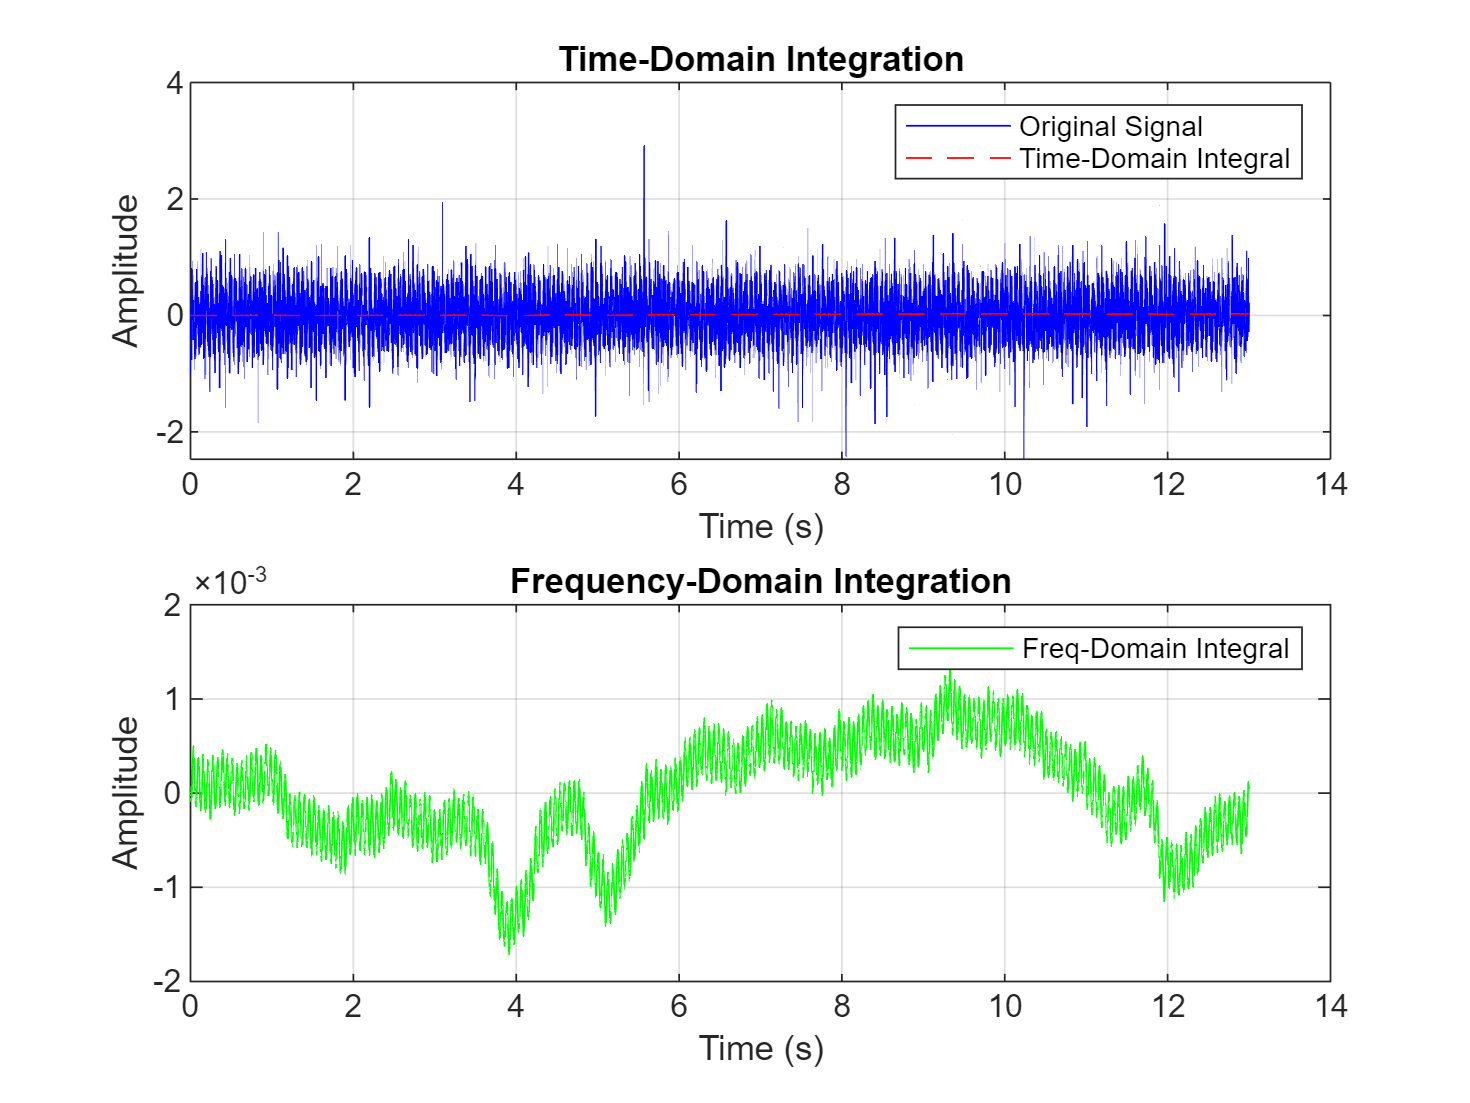

% Avoid division by zero at ω = 0
omega(1) = 1e-6; % Prevents division by zero

% Apply integration in the frequency domain
Y_int_f = fft(x) ./ (1j * omega); 

% Compute inverse FFT to return to time domain
y_int_f = ifft(Y_int_f, 'symmetric');

% Plot results
subplot(2,1,2);
plot(t, y_int_f, 'g', 'DisplayName', 'Freq-Domain Integral');
legend;
xlabel('Time (s)');
ylabel('Amplitude');
title('Frequency-Domain Integration');
grid on;

TF = isoutlier(x)

TF = 40625×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


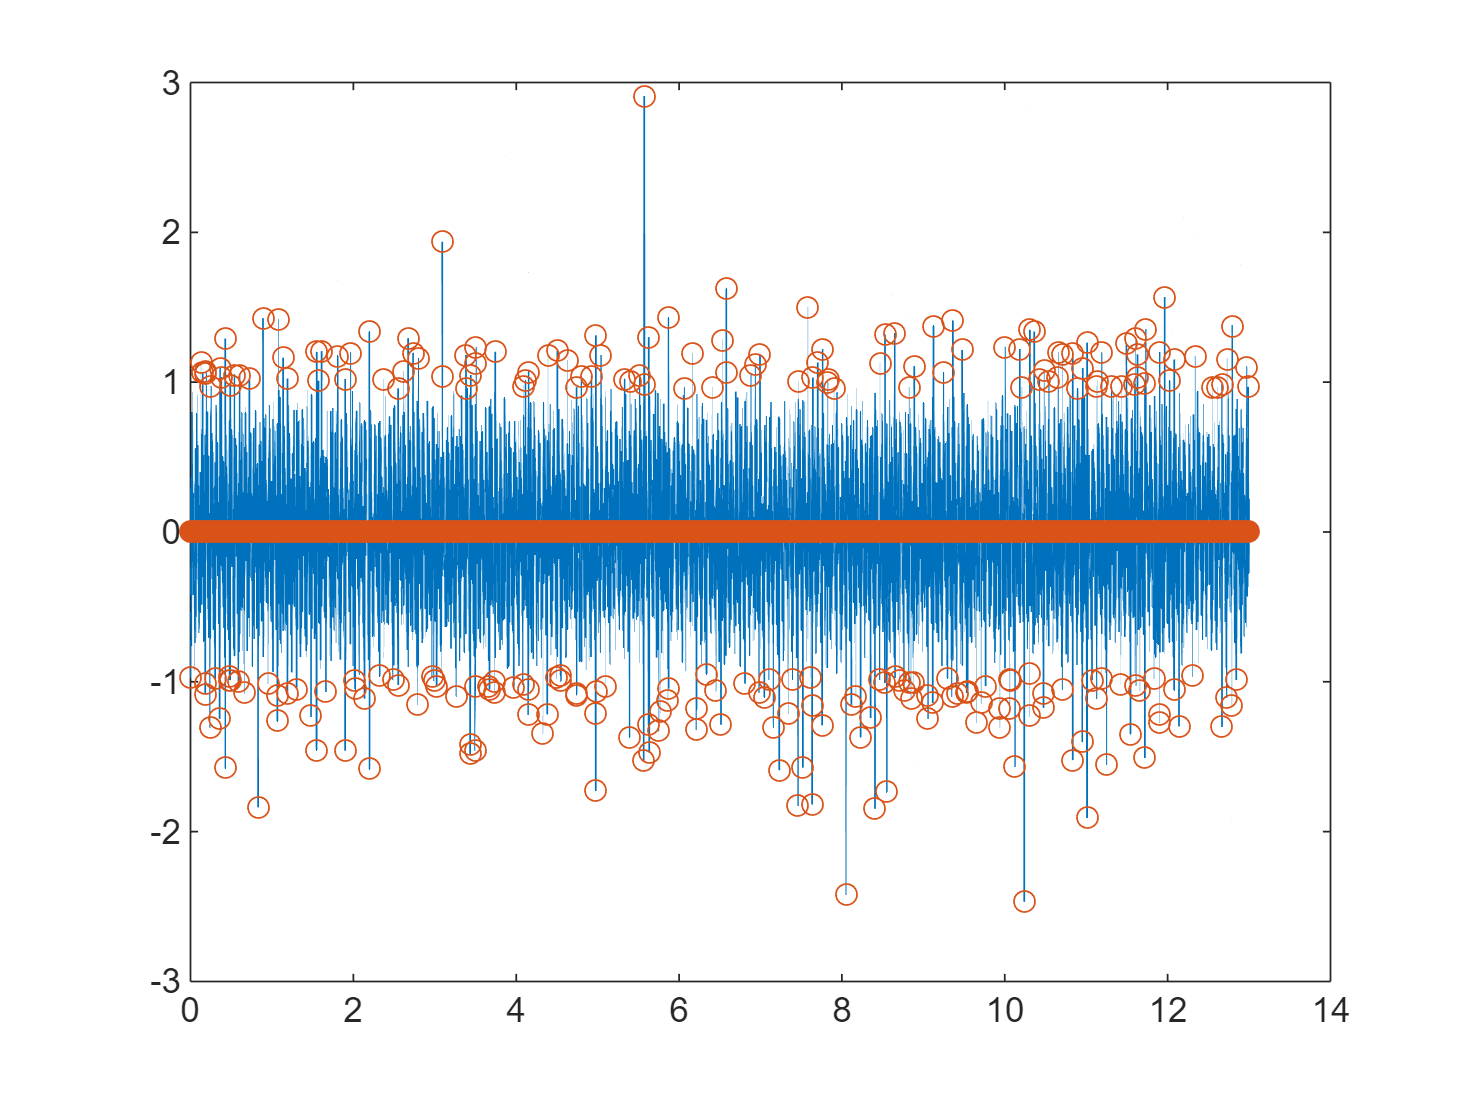

figure
plot(t,x,'-',t,x.*TF,'o')

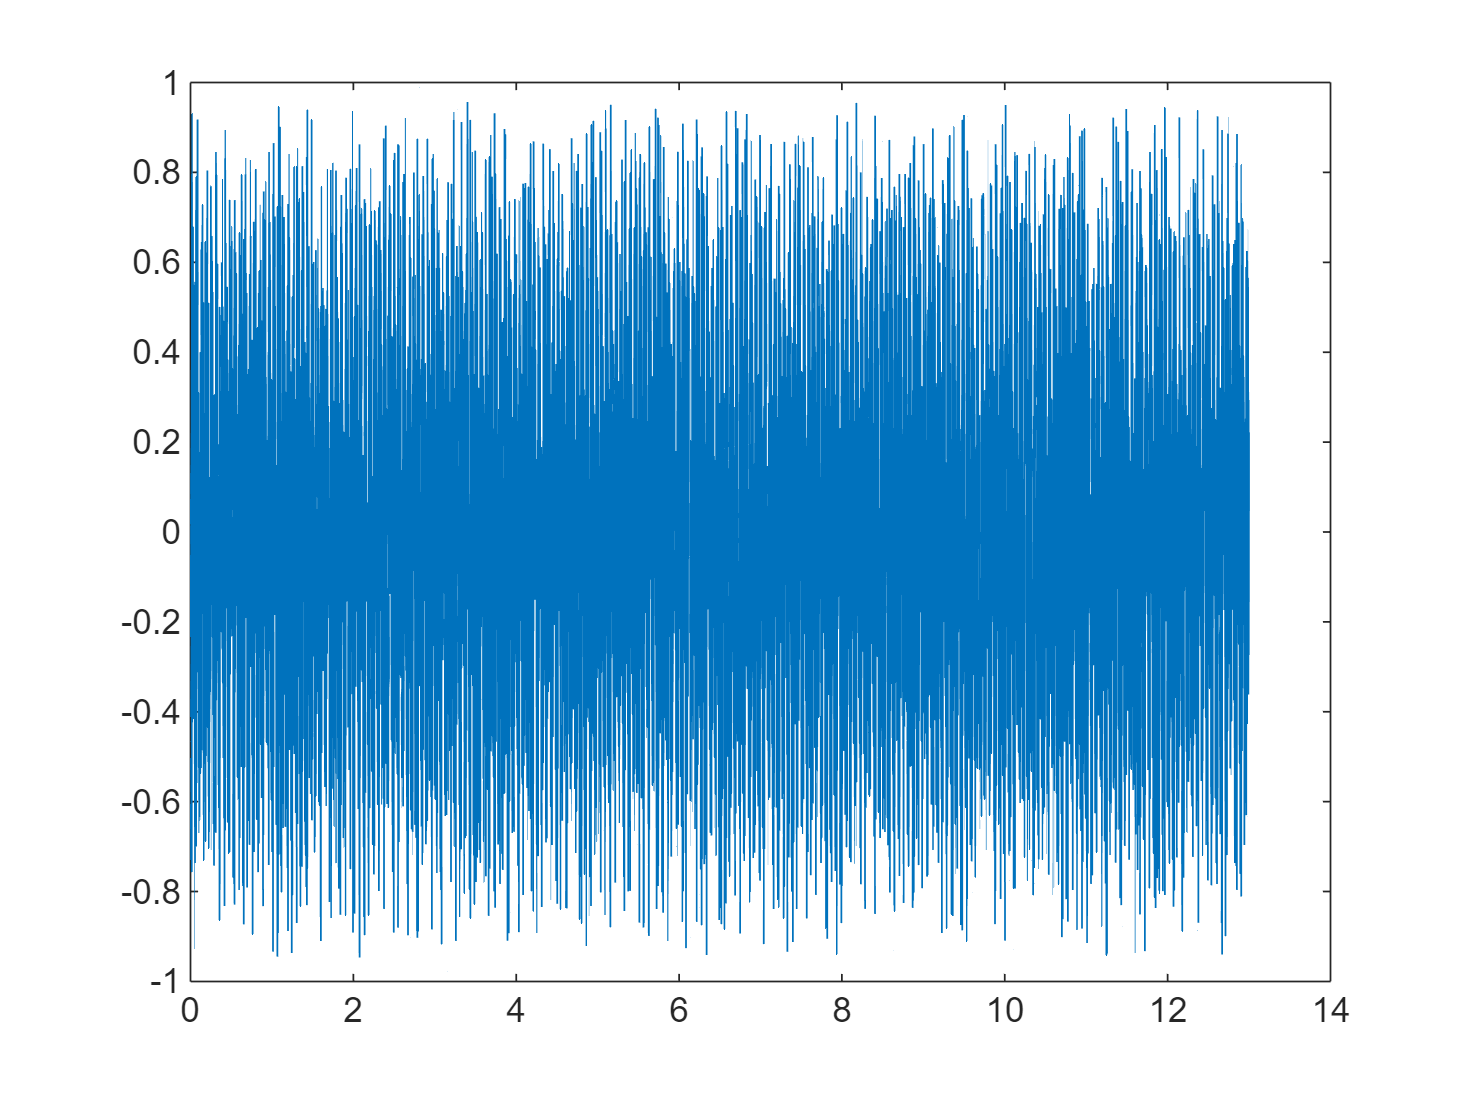

plot(t,x-x.*TF)